## Week 3 - Part 1

Dave Hill - Oregon State University

In this script, we will explore various types of flow control. If you are coming to Matlab from another programming language, a lot of this will be familiar. There are some differences in syntax between Matlab, Fortran, Python, and so on, but the general ideas are the same.

clear all
close all
home

### For Loops

Let us start with for loops. A for loop allows a piece of code to repeatedly executed. A for loop is distinguished by a 'loop counter' variable. A for loop is typically used when the number of iterations is known PRIOR to going into the loop. The general structure is:

Here is a simple example:

for n=1:100
    x(n)=sin(n*pi/10);
end
figure(1)
plot(x)
title('simple plot created with for loop')

Here is (seemingly) the same code, but the output is odd...why??

for n=1:100
    x=sin(n*pi/10);
end
figure(2)
plot(x) 
title('Can you find the error?')

What if loop is empty?


for n=1:100
end

disp('Did anything useful happen? Is this an error or is this behaving properly?')

You can 'nest' loops by looping over multiple counter variables for example, make a gaussian 'bump' and plot it. Note: the tic / toc commands are a way of computing the time that the computations are requiring. This can be a useful tool for seeing when your code is, or is not, efficient.

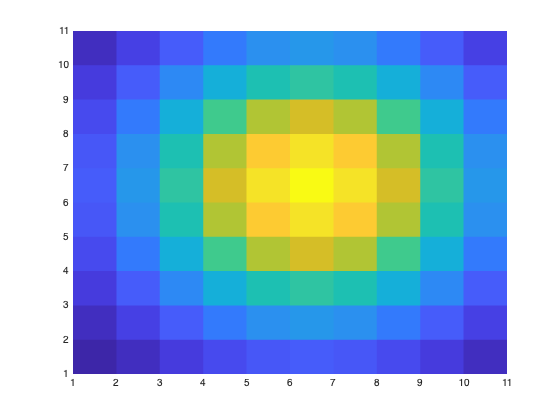


tic
for x=1:11
    for y=1:11
        z(x,y)=exp(-((x-6)/4)^2-((y-6)/4)^2);
    end
end
figure(3)
pcolor(z);
shading flat

toc

Elapsed time is 0.455379 seconds.


Ok that was pretty fast, but 'coarse' (only 11 x 11 cells). Try:

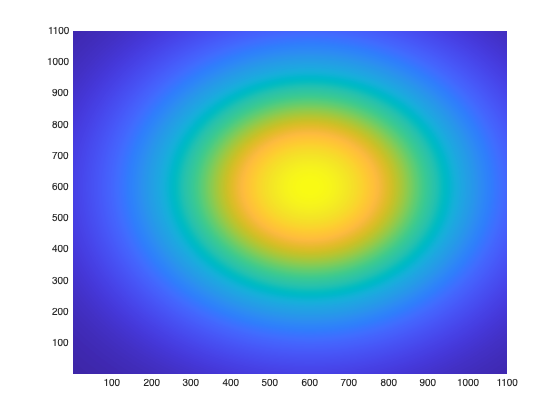


clear all
tic
for x=1:1100
    for y=1:1100
        z(x,y)=exp(-((x-600)/400)^2-((y-600)/400)^2);
    end
end
figure(4)
pcolor(z); shading flat

toc

Elapsed time is 1.834601 seconds.


Note: the execution time is not dramatically different...This is pretty sneaky of Matlab. Years ago, this 'nested loop' approach would have been really slow, since more than 1 million calculations are being carried out. However, now, Matlab automatically looks for code inefficiecies (and nested loops are very inefficient) and corrects them automatically...

Notes. The 'loop variable' does not need to run from 1 to N in increments of 1. That IS the default, if write something like for n = 1:N. You can have things count backwards:

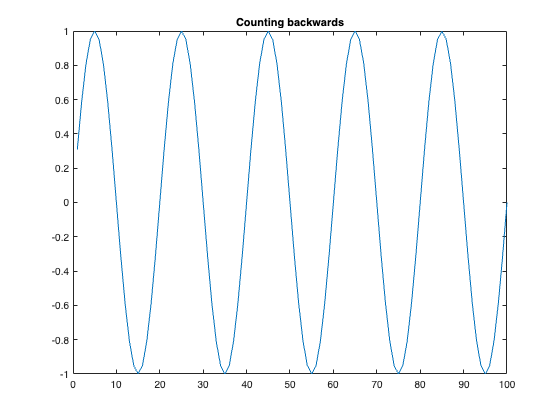


for n=100:-1:1
    x(n)=sin(n*pi/10);
end
figure(5)
plot(x)
title('Counting backwards')

But, can you also 'count' by fractions of an integer? For example

for n=1:.1:100
    x(n)=sin(n*pi/10);
end

Array indices must be positive integers or logical values.

Ok, so what went wrong above?? --> can NOT have a decimal as an index...If, for some reason, you MUST count by some non-integer interval or over some range (say, negative integers) that will give you problems in terms of a subscript, you can bring in a placholder counter variable. Here is an example

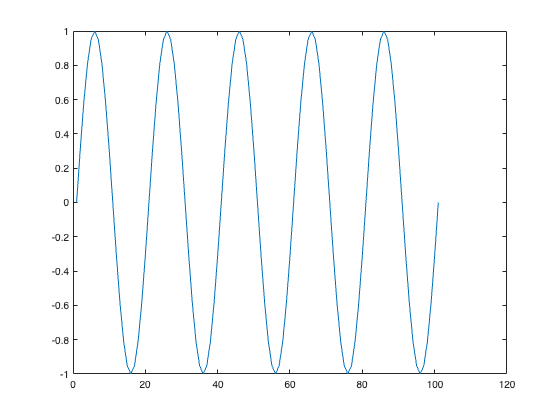

counter=0; 
for n = 0: 0.1: 10 
	counter = counter + 1;
	x(counter) = sin(n*pi); %so the thing in () is ALWAYS an integer...
end
figure
plot(x)

### While Loops

Next, let us consider while loops. These are similar to for loops in that the general idea is to repeatedly execute some piece of code. However, the key difference is that, where a for loop uses a finite 'counter' to iterate through the code, a while loop uses some boolean (true or false) condition to determine whether or not to carry out another iteration. The general format is:

What follows the 'while' is typically a relational operator, such as >,  <, ==, >=, and so on. See [here](https://www.mathworks.com/help/matlab/relational-operators.html) for more information. Also, note that you can use boolean operators such as 'and,' 'or,' 'not' and so on. See [here](https://www.mathworks.com/help/matlab/logical-operations.html) for more information.

Here is a simple example

close all
clear all
clc

n=1;
while n<10
    disp(['n = ' num2str(n)])
    n=n+1;
end

disp('Any key to continue')
pause

A potential problem with while loops is that you might get in a situation where the boolean argument is NEVER false and you are stuck in an infinite loop. For example, if you forget to 'increment' the counter. Try running this section to execute the code below....NOTE: you will need to use ctl-c to kill it!

n=1;
while n<10
    disp(['n = ' num2str(n)])
end

n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 1
n = 

You can safeguard against this with a break command. Note that the example below uses an 'if' loop which we have not discussed yet, so sit tight on that until later.

n=1;
num_iterations=0;
while n<10
    disp(['n = ' num2str(num_iterations)])
    if num_iterations>25
        disp(['terminated at ' num2str(num_iterations) ' iterations'])
        break
    end
    num_iterations=num_iterations+1;
end

### If Statements

Third, let us consider 'if' statments. These are not 'loops' in the sense that code does not get repeated. Rather, an if statement uses a boolean condition to decide whether or not to execute a certain piece of code. At its simplest, it looks like

Let us look at a simple example below.

f=6;
%check if f is even
if mod(f,2)==0
    disp('f is even')
end

Ok, well that was easy. If a certain condition is satisfied, then some code is executed. If not, then NOTHING is done. A slight variation is:

And, an example:

f=5;
%check if f is even
if mod(f,2)==0
    disp('f is even')
else
    disp('f is odd')
end

In this case, if the boolean condition is not satisfied, rather than NOTHING happening, something ELSE happens. Yet another variation is

With an example:

f=0
%check if f greater than zero, less than zero, or zero
if f>0
    disp('f is positive')
elseif f<0
    disp('f is negative')
else
    disp('looks like f is zero')
end

So, the 'else' is simply a 'catch-all' category. You can have as many elseif statements as you want, in between the original *if* and the final *else*. 

## Switch Statements

Finally, let us look at the 'switch' command. This is really just like a series of if / elseif commands. In many cases, using switch results in cleaner, more compact code. Here is an example

val=4;
switch val % we are 'switching' or 'testing' based on the value in the variable val
    case 1
        disp('one')
    case 2
        disp('two')
    case 3
        disp('three')
    otherwise
        disp('something else')
end

something else
